## `EXPERIMENT 3`

Fs = 40e3;
t = 0:1/Fs:1-1/Fs;
N_t = length(t);
N_response = N_t/10;

### `Input:`

n = 1;
input = zeros(1,N_t);
for j = 0:1/Fs:1-1/Fs                                %9437840590
    if n<=N_response
        input(n) = symbol(9,j);
        n = n+1;
    elseif n<=2*N_response
        input(n) = symbol(4,j);
        n = n+1;
    elseif n<=3*N_response
        input(n) = symbol(3,j);
        n = n+1;
    elseif n<=4*N_response
        input(n) = symbol(7,j);
        n = n+1;
    elseif n<=5*N_response
        input(n) = symbol(8,j);
        n = n+1;
    elseif n<=6*N_response
        input(n) = symbol(4,j);
        n = n+1;
    elseif n<=7*N_response
        input(n) = symbol(0,j);
        n = n+1;
    elseif n<=8*N_response
        input(n) = symbol(5,j);
        n = n+1;
    elseif n<=9*N_response
        input(n) = symbol(9,j);
        n = n+1;
    elseif n<=10*N_response
        input(n) = symbol(0,j);
        n = n+1;
    end
end

### `Plot of the input:`

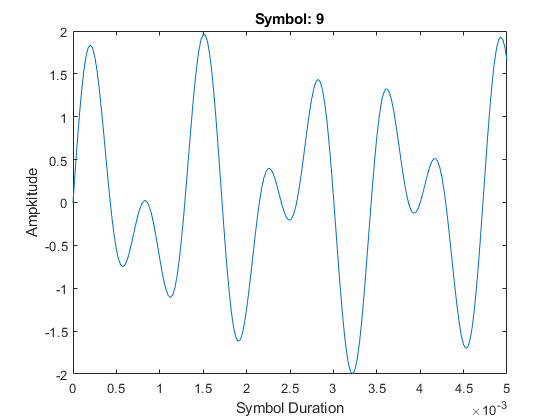

plot(t,input);
axis([0 0.005 -2 2]);
xlabel('Symbol Duration');
ylabel('Ampkitude');
title('Symbol: 9')

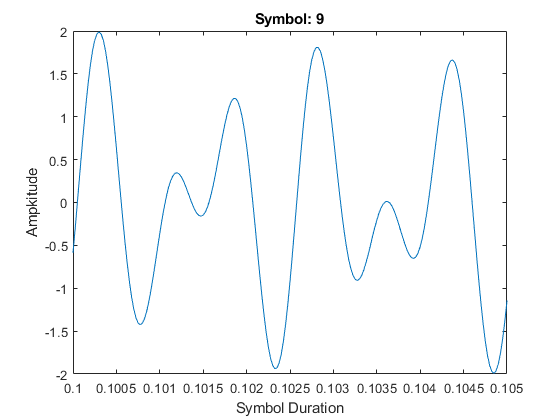

plot(t,input);
axis([0.1 0.105 -2 2]);
xlabel('Symbol Duration');
ylabel('Ampkitude');
title('Symbol: 9')

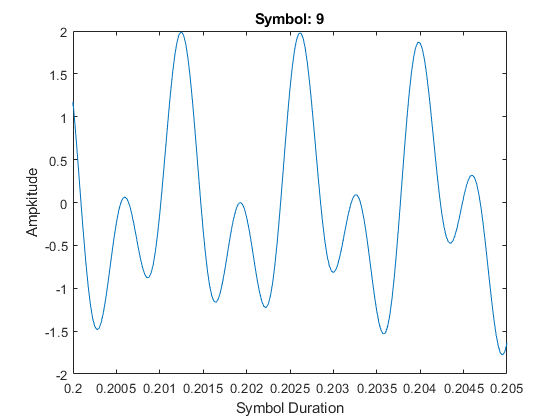

plot(t,input);
axis([0.2 0.205 -2 2]);
xlabel('Symbol Duration');
ylabel('Ampkitude');
title('Symbol: 9')

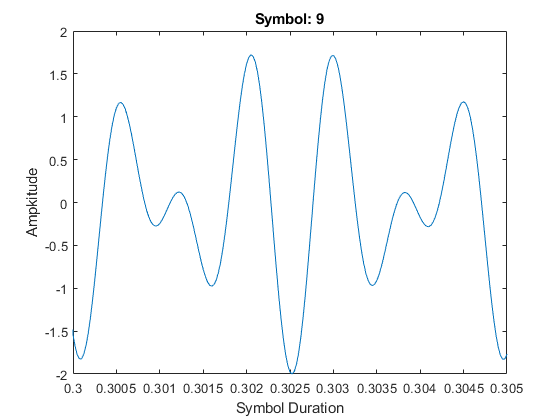

plot(t,input);
axis([0.3 0.305 -2 2]);
xlabel('Symbol Duration');
ylabel('Ampkitude');
title('Symbol: 9')

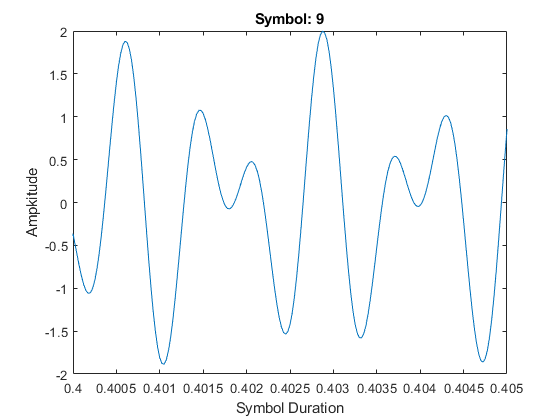

plot(t,input);
axis([0.4 0.405 -2 2]);
xlabel('Symbol Duration');
ylabel('Ampkitude');
title('Symbol: 9')

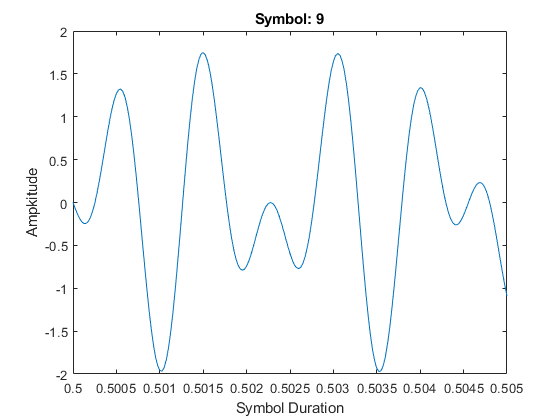

plot(t,input);
axis([0.5 0.505 -2 2]);
xlabel('Symbol Duration');
ylabel('Ampkitude');
title('Symbol: 9')

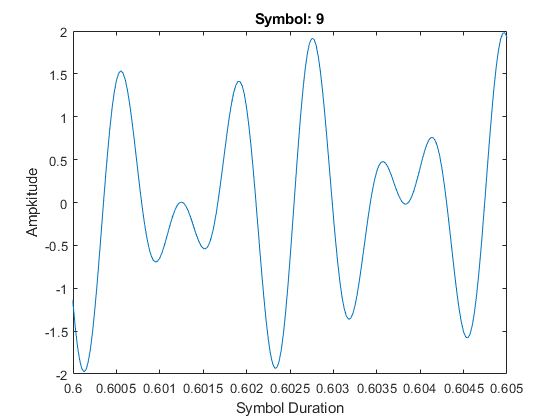

plot(t,input);
axis([0.6 0.605 -2 2]);
xlabel('Symbol Duration');
ylabel('Ampkitude');
title('Symbol: 9')

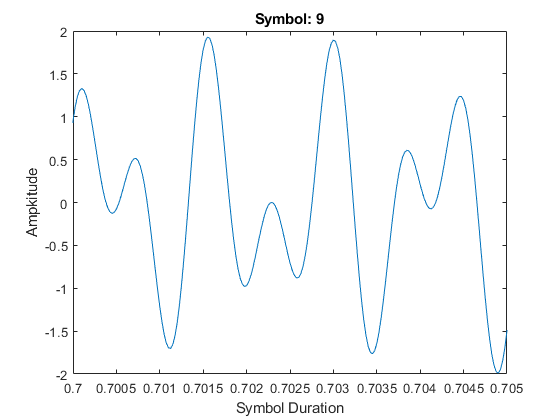

plot(t,input);
axis([0.7 0.705 -2 2]);
xlabel('Symbol Duration');
ylabel('Ampkitude');
title('Symbol: 9')

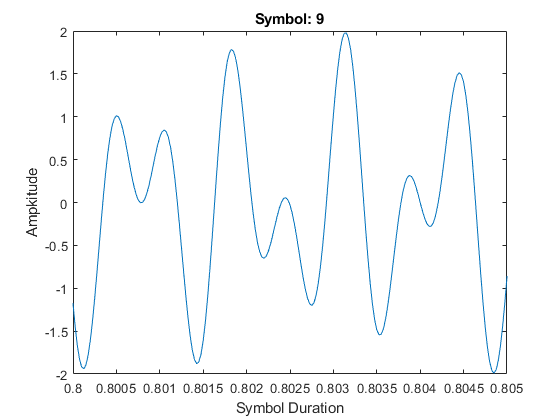

plot(t,input);
axis([0.8 0.805 -2 2]);
xlabel('Symbol Duration');
ylabel('Ampkitude');
title('Symbol: 9')

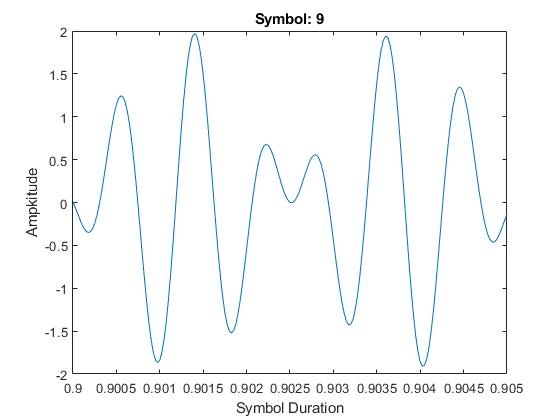

plot(t,input);
axis([0.9 0.905 -2 2]);
xlabel('Symbol Duration');
ylabel('Ampkitude');
title('Symbol: 9')

### `Analysis:`

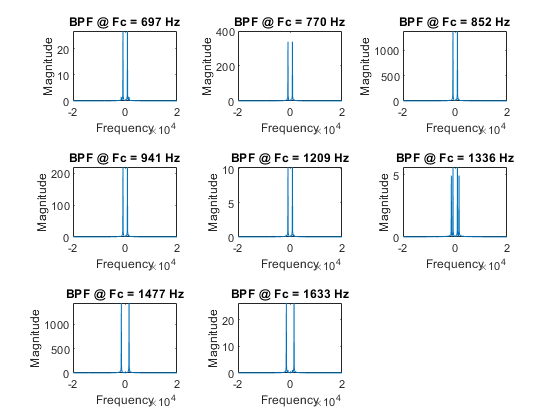

Symbol_1 = filtbank(input, 1, N_response);
Symbol_2 = filtbank(input, 2, N_response);

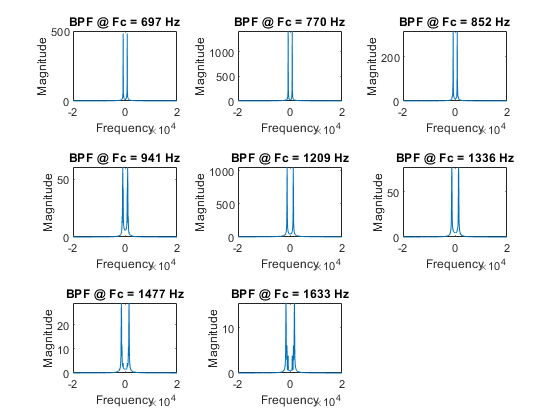

Symbol_3 = filtbank(input, 3, N_response);

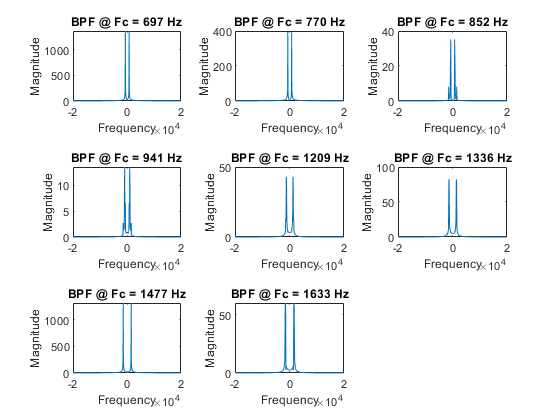

Symbol_4 = filtbank(input, 4, N_response);

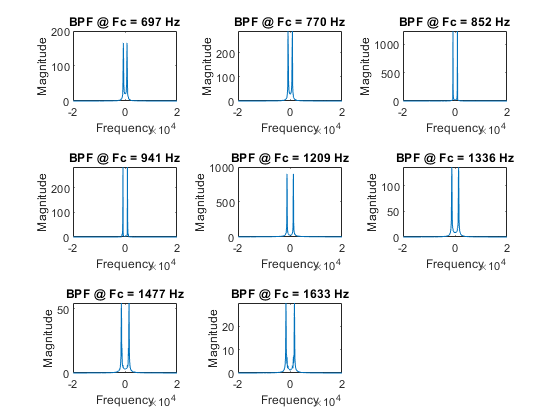

Symbol_5 = filtbank(input, 5, N_response);

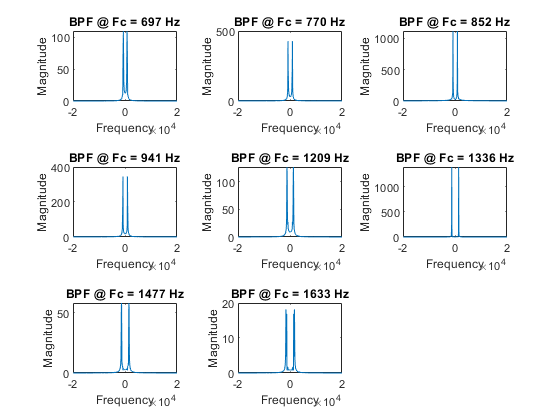

Symbol_6 = filtbank(input, 6, N_response);

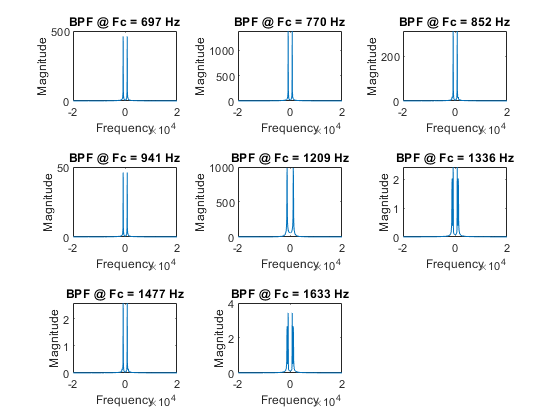

Symbol_7 = filtbank(input, 7, N_response);

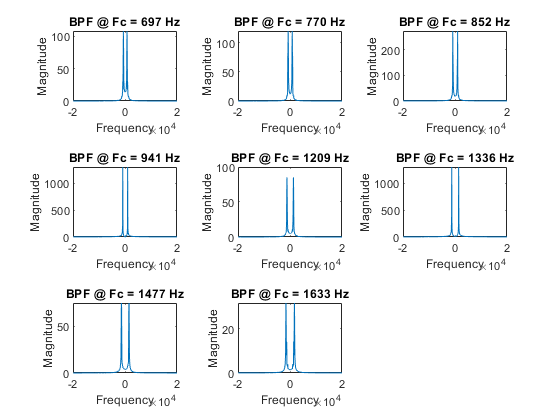

Symbol_8 = filtbank(input, 8, N_response);

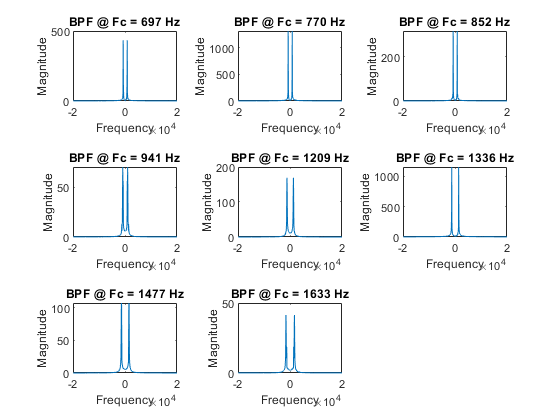

Symbol_9 = filtbank(input, 9, N_response);

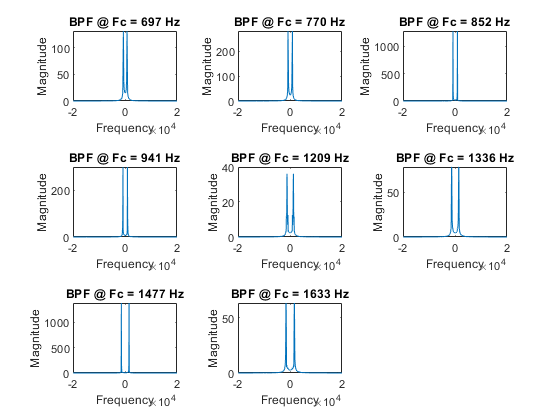

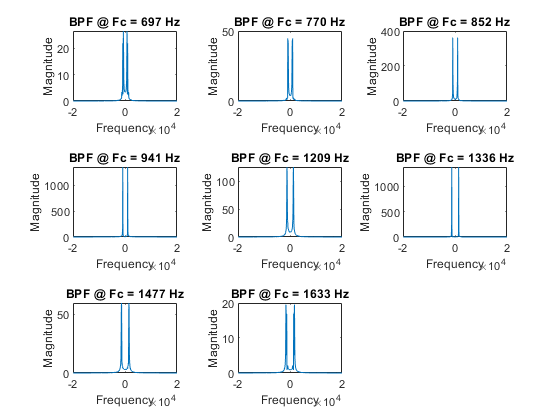

Symbol_10 = filtbank(input, 10, N_response);

### `DTMF Decoder:`

function symbole = filtbank(Input,S,N_Response)
    Fs = 40e3;
    f_1 = 697;
    f_2 = 770;
    f_3 = 852;
    f_4 = 941;
    f_5 = 1209;
    f_6 = 1336;
    f_7 = 1477;
    f_8 = 1633;
    freq = (Fs/512) *(-255:1:256);
    
    beta = 1;
    L = 300;
    x = 1:1:L;
    
    h_1 = beta*cos(2*pi*f_1*x/Fs);
    h_2 = beta*cos(2*pi*f_2*x/Fs);
    h_3 = beta*cos(2*pi*f_3*x/Fs);
    h_4 = beta*cos(2*pi*f_4*x/Fs);
    h_5 = beta*cos(2*pi*f_5*x/Fs);
    h_6 = beta*cos(2*pi*f_6*x/Fs);
    h_7 = beta*cos(2*pi*f_7*x/Fs);
    h_8 = beta*cos(2*pi*f_8*x/Fs);
    
    j = 1;
    for i = (S-1)*N_Response+1:1:(S)*N_Response
        signal(j) = Input(i);
        j = j+1;
    end
    
        y_1 = filtfilt(h_1,1,signal);
        y_2 = filtfilt(h_2,1,signal);
        y_3 = filtfilt(h_3,1,signal);
        y_4 = filtfilt(h_4,1,signal);
        y_5 = filtfilt(h_5,1,signal);
        y_6 = filtfilt(h_6,1,signal);
        y_7 = filtfilt(h_7,1,signal);
        y_8 = filtfilt(h_8,1,signal);
        
        y1 = abs(fftshift(fft(y_1,512)));
        y2 = abs(fftshift(fft(y_2,512)));
        y3 = abs(fftshift(fft(y_3,512)));
        y4 = abs(fftshift(fft(y_4,512)));
        y5 = abs(fftshift(fft(y_5,512)));
        y6 = abs(fftshift(fft(y_6,512)));
        y7 = abs(fftshift(fft(y_7,512)));
        y8 = abs(fftshift(fft(y_8,512)));
        
        y1_rms = max(y1);
        y2_rms = max(y2);
        y3_rms = max(y3);
        y4_rms = max(y4);
        y5_rms = max(y5);
        y6_rms = max(y6);
        y7_rms = max(y7);
        y8_rms = max(y8);
        
        y_rms = [y1_rms y2_rms y3_rms y4_rms y5_rms y6_rms y7_rms y8_rms];
        
        I1 = find(y_rms == max(y_rms));
        y_rms(I1) = 0;
        I2 = find(y_rms == max(y_rms));
        
        if I1>I2 
            temp = I2;
            I2 = I1;
            I1 = temp;
        end
        
        if isequal([I1,I2],[1,5])
            symbole = '1';
        elseif isequal([I1,I2], [1,6])
            symbole = '2';
        elseif isequal([I1,I2], [1,7])
            symbole = '3';
        elseif isequal([I1,I2], [1,8])
            symbole = 'A';
        elseif isequal([I1,I2], [2,5])
            symbole = '4';
        elseif isequal([I1,I2], [2,6])
            symbole = '5';
        elseif isequal([I1,I2], [2,7])
            symbole = '6';
        elseif isequal([I1,I2], [2,8])
            symbole = 'B';
        elseif isequal([I1,I2],[3,5])
            symbole = '7';
        elseif isequal([I1,I2], [3,6])
            symbole = '8';
        elseif isequal([I1,I2], [3,7])
            symbole = '9';
        elseif isequal([I1,I2], [3,8])
            symbole = 'C';
        elseif isequal([I1,I2], [4,5])
            symbole = '*';
        elseif isequal([I1,I2], [4,6])
            symbole = '0';
        elseif isequal([I1,I2], [4,7])
            symbole = '#';
        elseif isequal([I1,I2], [4,8])
            symbole = 'D';
        else
            symbole = [I1,I2];
        end
        
         tiledlayout("flow");
        nexttile;
        plot(freq,y1/N_Response);
        xlabel('Frequency');
        ylabel('Magnitude');
        title('BPF @ Fc = 697 Hz');
        nexttile;
        plot(freq,y2/N_Response);
        xlabel('Frequency');
        ylabel('Magnitude');
        title('BPF @ Fc = 770 Hz');
        nexttile;
        plot(freq,y3/N_Response);
        xlabel('Frequency');
        ylabel('Magnitude');
        title('BPF @ Fc = 852 Hz');
        nexttile;
        plot(freq,y4/N_Response);
        xlabel('Frequency');
        ylabel('Magnitude');
        title('BPF @ Fc = 941 Hz');
        nexttile;
        plot(freq,y5/N_Response);
        xlabel('Frequency');
        ylabel('Magnitude');
        title('BPF @ Fc = 1209 Hz');
        nexttile;
        plot(freq,y6/N_Response);
        xlabel('Frequency');
        ylabel('Magnitude');
        title('BPF @ Fc = 1336 Hz');
        nexttile;
        plot(freq,y7/N_Response);
        xlabel('Frequency');
        ylabel('Magnitude');
        title('BPF @ Fc = 1477 Hz');
        nexttile;
        plot(freq,y8/N_Response);
        xlabel('Frequency');
        ylabel('Magnitude');
        title('BPF @ Fc = 1633 Hz');
end

### `DTMF Encoder:`

function sig = symbol(sym,i)
    if sym == 1
        sig = sin(2*pi*697*i) + sin(2*pi*1209*i);
    elseif sym == 2
        sig = sin(2*pi*697*i) + sin(2*pi*1336*i);
    elseif sym == 3
        sig = sin(2*pi*697*i) + sin(2*pi*1477*i);
    elseif sym == 'A' %A
        sig = sin(2*pi*697*i) + sin(2*pi*1633*i);
    elseif sym == 4
        sig = sin(2*pi*770*i) + sin(2*pi*1209*i);
    elseif sym == 5
        sig = sin(2*pi*770*i) + sin(2*pi*1336*i);
    elseif sym == 6
        sig = sin(2*pi*770*i) + sin(2*pi*1477*i);
    elseif sym == 'B'%B
        sig = sin(2*pi*770*i) + sin(2*pi*1633*i);
    elseif sym == 7
        sig = sin(2*pi*852*i) + sin(2*pi*1209*i);
    elseif sym == 8
        sig = sin(2*pi*852*i) + sin(2*pi*1336*i);
    elseif sym == 9
        sig = sin(2*pi*852*i) + sin(2*pi*1477*i);
    elseif sym == 'C' %C
        sig = sin(2*pi*852*i) + sin(2*pi*1633*i);
    elseif sym == '*' %*
        sig = sin(2*pi*941*i) + sin(2*pi*1209*i);
    elseif sym == 0
        sig = sin(2*pi*941*i) + sin(2*pi*1336*i);
    elseif sym == '#' %#
        sig = sin(2*pi*941*i) + sin(2*pi*1477*i);
    elseif sym == 'D' %D
        sig = sin(2*pi*941*i) + sin(2*pi*1633*i);
    end
end